# Appendix: Matlab Code for Each Parts (Live Script)

## Part 1:

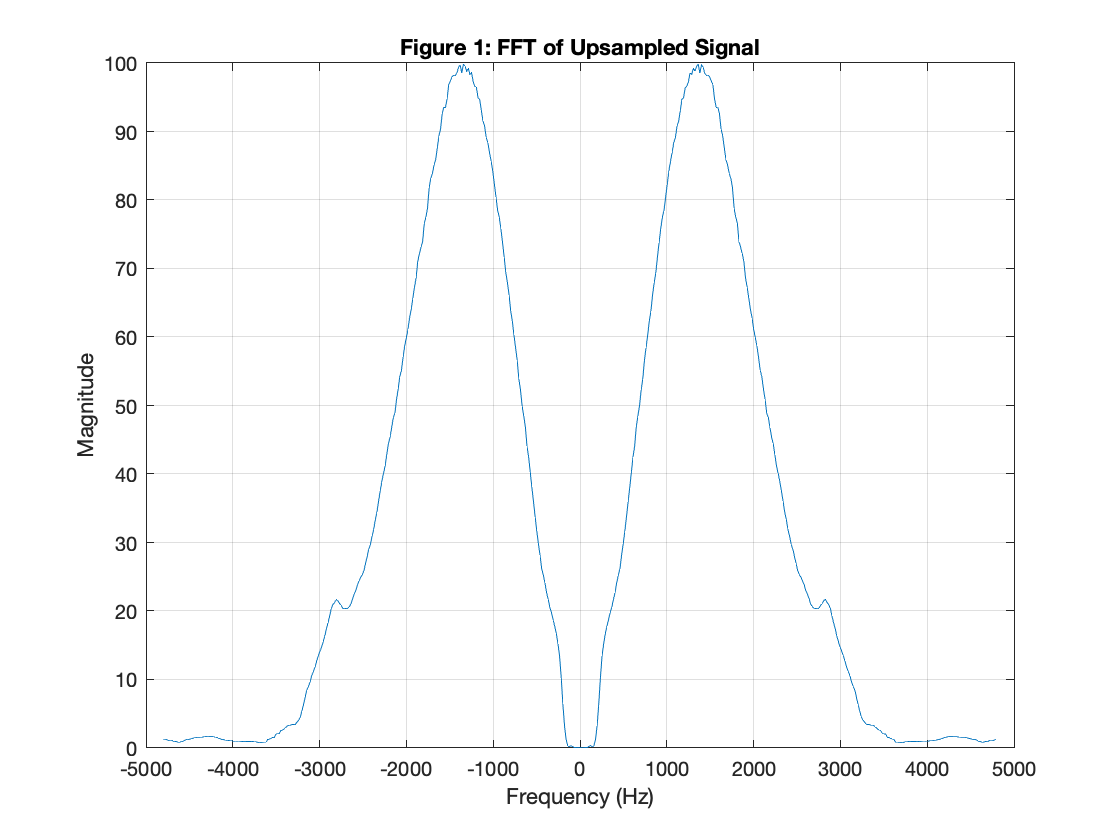

M = readmatrix("c0.txt")';
M = M(1:end-2)'; D = 512; L = 256;
upsampled = interp1(1:L, M(:, 1), linspace(1, L, 299), "spline");
upsampled = [upsampled zeros(1, (D - length(upsampled)))];

% Take the FFT and plot magnitude
Upsampled = (fftshift(fft(upsampled)));
tmp = linspace(-4800, 4800, 512);
figure();plot(tmp,abs(Upsampled)); title("Figure 1: FFT of Upsampled Signal"); 
xlabel("Frequency (Hz)"); ylabel("Magnitude"); grid on; 

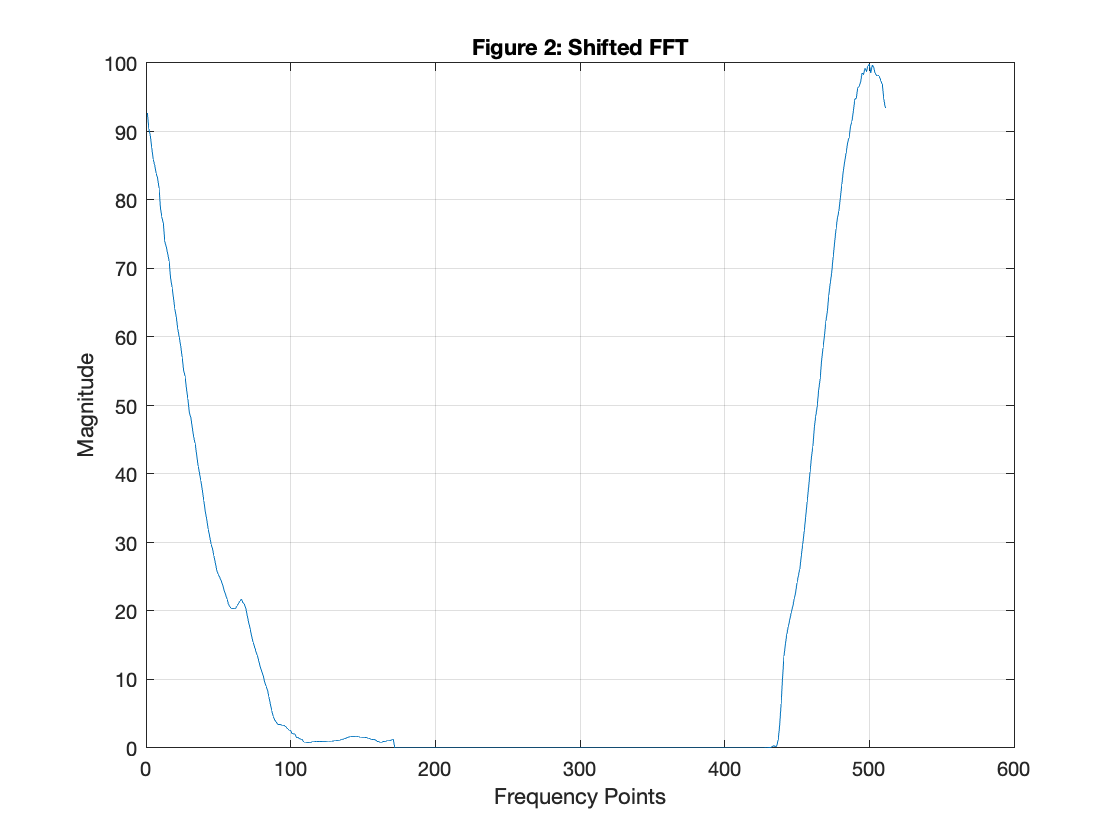


% Zero the negative frequencies and perform a cyclically shift
Upsampled(1:256) = zeros(1, 256); 
Upsampled = circshift(Upsampled, -341); % Shift so that "max" is at sample 1
figure(); plot(abs(Upsampled)); title("Figure 2: Shifted FFT"); grid on;
xlabel("Frequency Points"); ylabel("Magnitude"); grid on;

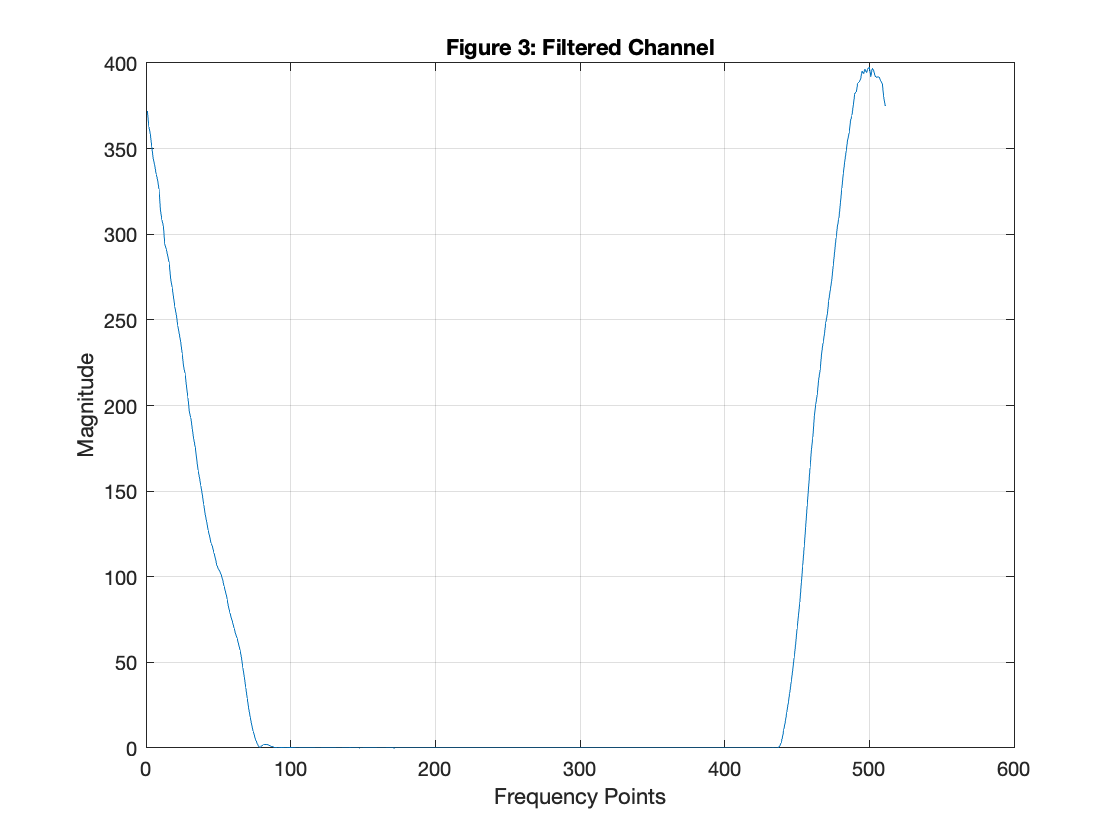

 %generate srrc response and determine the index in which srrc dips below
 %30db
N = 512; beta = 0.15;
srrc_signal = zeros(1, N); 
for i=-256:255
    srrc_signal(i+257) = SRRC(beta, i);
end
thirty_dB = (srrc_signal(257) / sqrt(1000));
idx = 1; 
for i=1:257
    if abs(srrc_signal(i)) > thirty_dB
        break;
    else
        idx = i;
    end
end

% Obtain the truncated SRRC filter and zero stuff the response
idx = idx + 1; M2 = 2*(257 - idx) + 1;
signal_new = zeros(1, M2); 
for i=(-floor(M2 / 2)):(floor(M2 / 2))
    signal_new(i + (floor(M2 / 2)) + 1) = SRRC(beta,i);
end
signal_new = [signal_new zeros(1, (D - length(signal_new)))];
srrc_filter = (fft(signal_new));

% filtered channel response, and plot the filtered channel
channel = srrc_filter .* Upsampled;
figure(); plot(abs(channel)); title("Figure 3: Filtered Channel"); grid on;
xlabel("Frequency Points"); ylabel("Magnitude"); grid on;

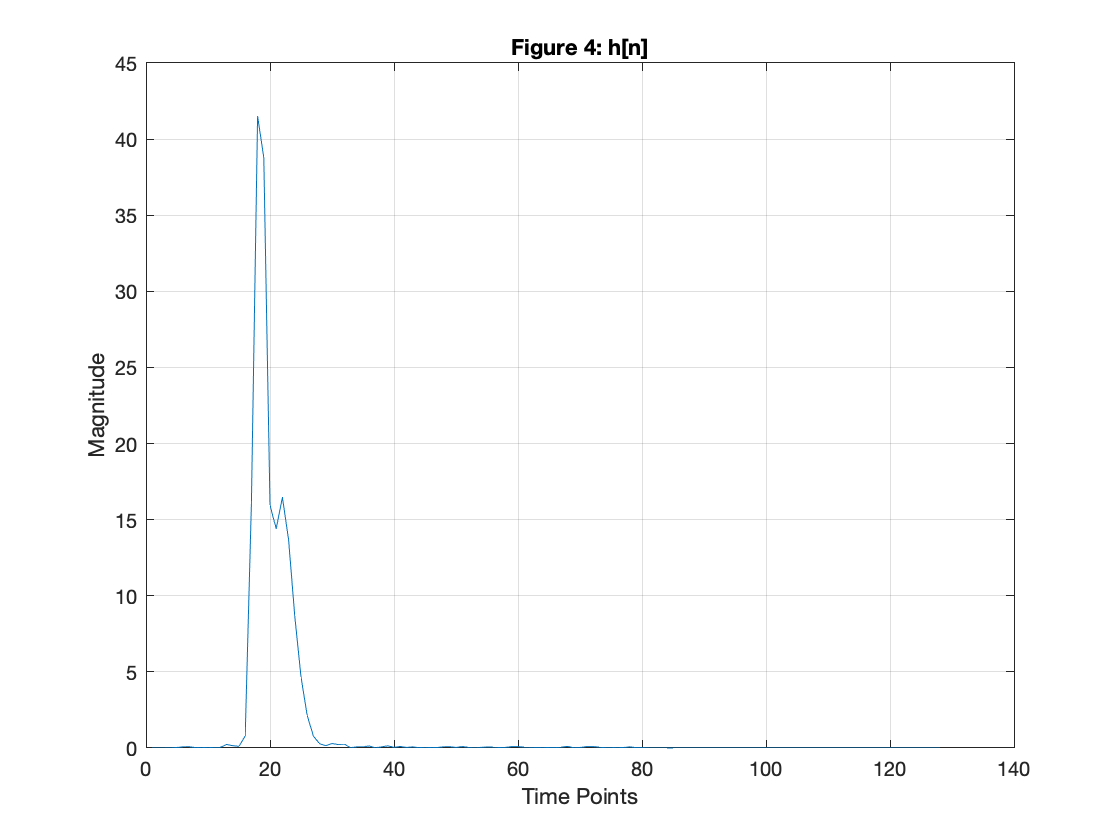


% compute ifft and down sample
time_representation = ifft(channel, D); % 512-point IFFT of channel
impulse_response = time_representation(1:4:end); 
figure(); plot(abs(impulse_response)); title("Figure 4: h[n]"); grid on;
xlabel("Time Points"); ylabel("Magnitude"); grid on;


% sum of squares for power
hpower = 0;
for i=1:128
    hpower = hpower + abs(impulse_response(i))^2;
end

hpower

hpower = 4.5070e+03

## Part 2: 

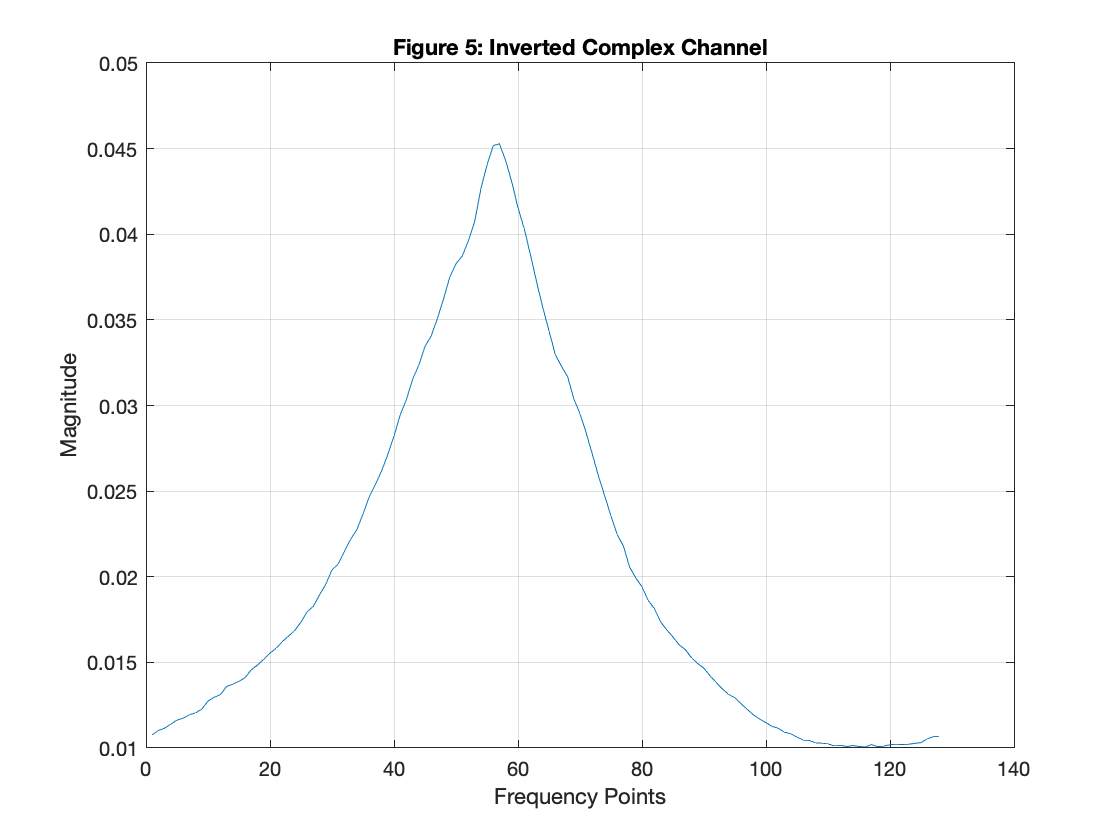

impulse_response_fft = (fft(impulse_response));
%invert the equalizer
inv_imp_fft = 1./impulse_response_fft;
figure(); plot(abs(inv_imp_fft)); title("Figure 5: Inverted Complex Channel"); grid on;
xlabel("Frequency Points"); ylabel("Magnitude"); grid on;

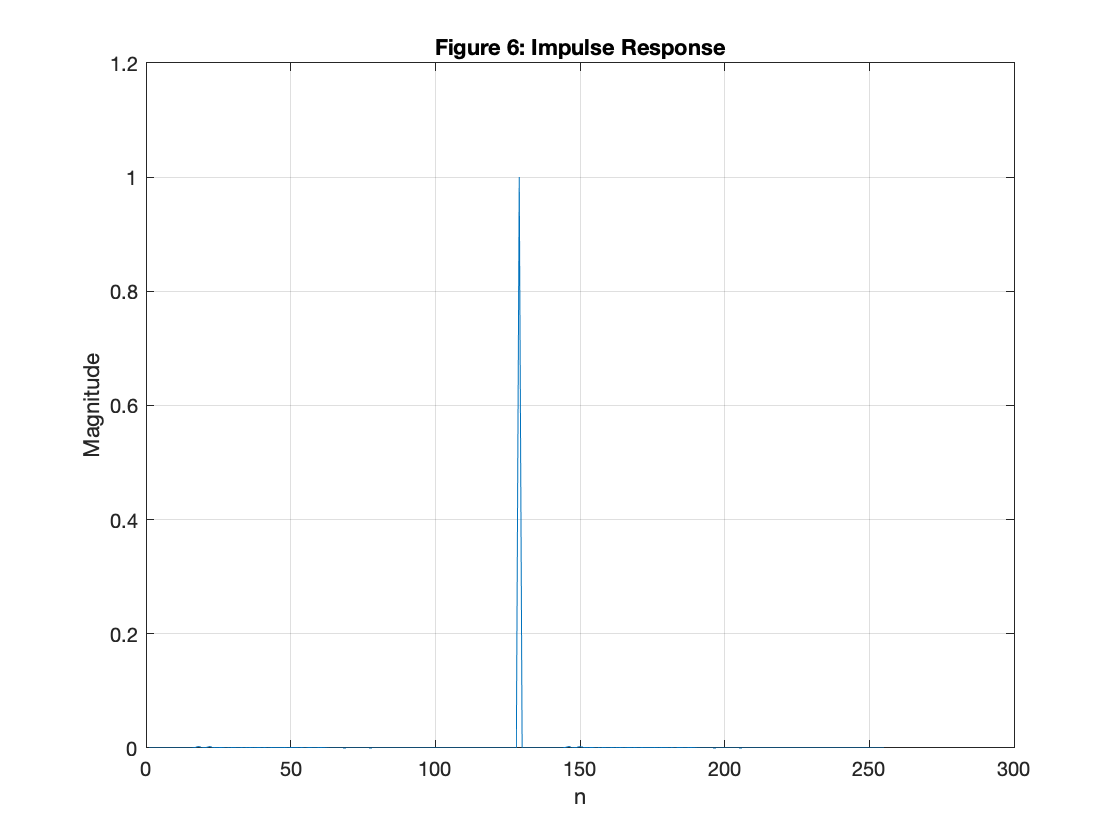


%obtain time domain representation of the inverted equalizer
inv_imp_time_domain = ifft(inv_imp_fft);
%figure(); plot(abs(inv_imp_time_domain));
inv_conv_channel = conv(inv_imp_time_domain,impulse_response);
figure(); plot(abs(inv_conv_channel)); title("Figure 6: Impulse Response"); grid on;
xlabel("n"); ylabel("Magnitude"); grid on;


%sum of squared absolute values for the four peaks
f_peak = max(abs(inv_conv_channel).^2);
sq_ab = sum(abs(inv_conv_channel).^2);
abs_max = f_peak.^2;
SIR = abs_max/(sq_ab-abs_max)

SIR = 1.0341e+04

nvar = 1/(sum(abs(impulse_response).^2) * 2000);

%compute the R matrix
R = zeros(128,128);
for i = 1:128
    for j = 1:128
        for k = 1:256
            con_h = conj(impulse_response);
            % make sure it's within the boundary
            if (k+1-i > 0) && (k+1-i <= 128) && (k+1-j > 0) && (k+1-j <= 128)
                R(i,j) = R(i,j) + con_h(1,k+1-i) * impulse_response(1,k+1-j);
            end
            if i == j
                R(i,j) = R(i,j) + 1/(sum(abs(impulse_response).^2) * 2000);
            end
        end
    end
    
end


%find the optimal d in which the SIR is minimized
%hd is the shifted h, re_delay is the optimal delay
hd=zeros(128,1);
re_delay = 0;
SIR = 0;
for d = 1:128
    hd_temp=zeros(128,1);
    for i = 1:128
        if d+1-i > 0
            hd_temp(i)=impulse_response(d+1-i);
        end
    end
    c_temp = R \ conj(hd_temp);
    temp_conv = conv(c_temp,impulse_response);
    m = max(abs(temp_conv));
    SIR_temp = m.^2/(sum(abs(temp_conv).^2)-m.^2);
    if SIR_temp > SIR
        SIR = SIR_temp;
        re_delay = d;
        hd = hd_temp;
        mmse = temp_conv;
    end
end

re_delay

re_delay = 52

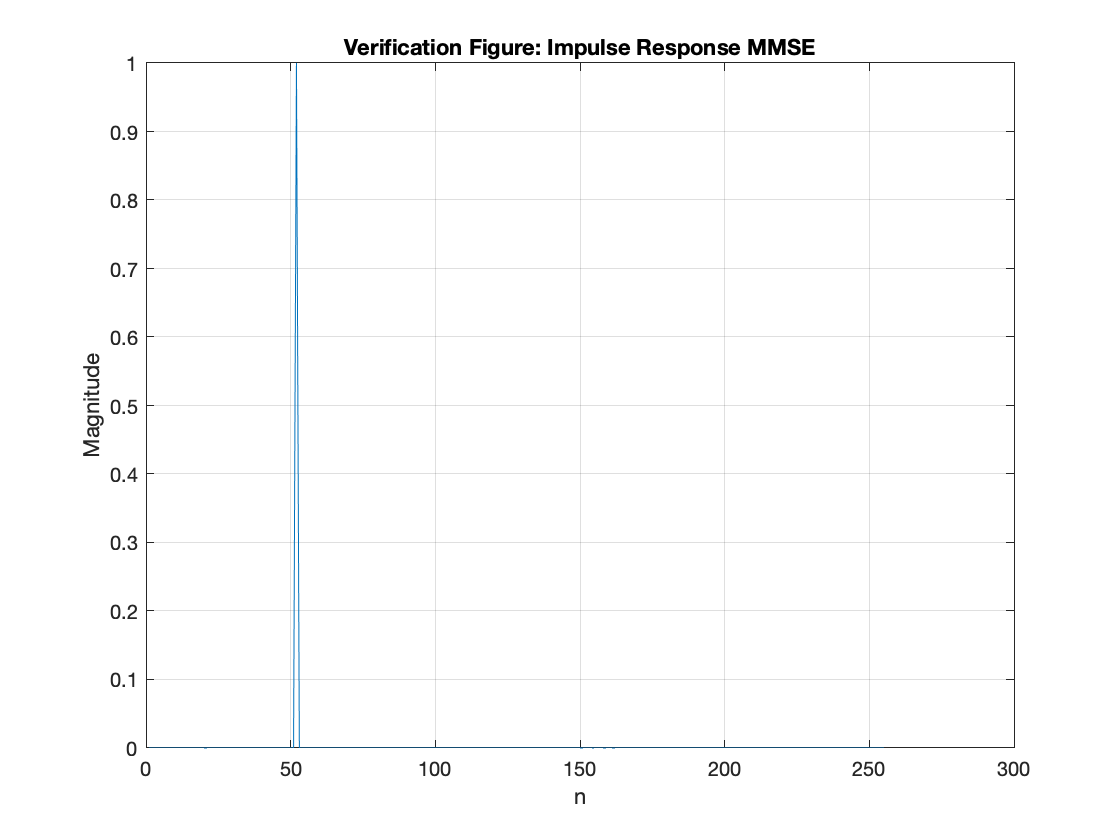


%compute c and convolve with h
c=R\conj(hd);
c_con_chan = conv(c,impulse_response);
%visualize the end product
figure();plot(abs(c_con_chan)); title("Verification Figure: Impulse Response MMSE"); grid on;
xlabel("n"); ylabel("Magnitude"); grid on;

%compute SIR
SIR_MMSE = max(abs(c_con_chan).^2)/(sum(abs(c_con_chan).^2)-abs(max(abs(c_con_chan))).^2)

SIR_MMSE = 1.5453e+09

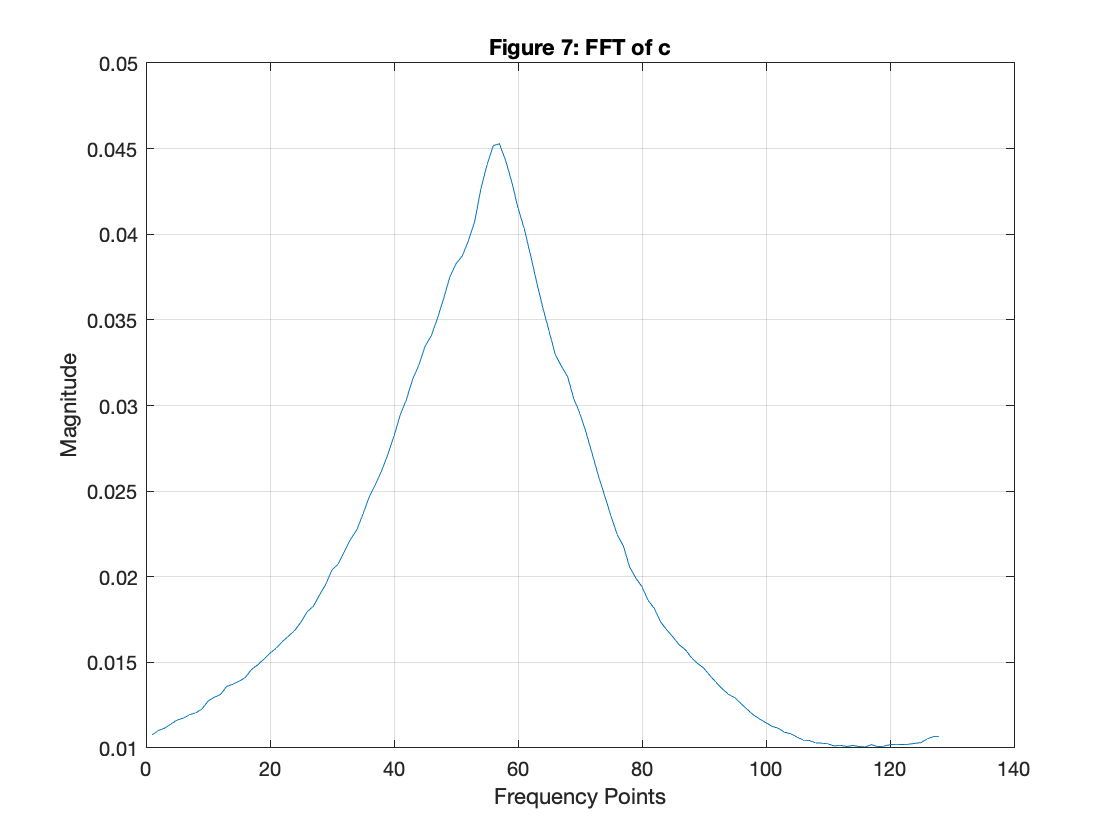


%plot the fft of the equalizer
figure();plot(abs(fft(c))); title("Figure 7: FFT of c"); grid on;
xlabel("Frequency Points"); ylabel("Magnitude"); grid on;

## Part 3:

w = zeros(128, 1); w(d) = 1; del = 2 / (128 * hpower * 100); j = sqrt(-1);
data = zeros(128, 1); u = zeros(128, 1); squared_error = 0; lim = 3000000;

for iter=1:lim
    % Randomly compute sampled data
    val = randsample([-1, 1], 1) * (1/sqrt(2)) + randsample([-1, 1], 1) * (j/sqrt(2));
    data = circshift(data, 1); data(1) = val;
    % zero mean complex Gaussian noise
    z = (normrnd(0, sqrt(nvar)) + j*normrnd(0, sqrt(nvar))) / sqrt(2);

    % Compute channel output
    val = 0;
    for i=1:128
        val = val + impulse_response(i) * data(i);
    end

    % Cyclically shift channel output into output array, and add val in front
    u = circshift(u, 1); u(1) = val + z;
    
    % Calculate the error  
    y = 0;
    for i=1:128
        y = y + u(i) * w(i);
    end
    e = data(re_delay) - y; 
    
    % Calculate squared error when iterations surpasses 95 percent
    % benchmark
    if iter >= 0.95 * lim
        squared_error = squared_error + abs(e)^2;
    end
    % Adjust the step size and update the w in gradient descent
    if iter > 1000000
        del = 2 / (128 * hpower * 1000);
    end
    w = w + del * e * conj(u);
end
%calculate the SINR
SINR = 0.05 * lim / squared_error 

SINR = 1.4180e+09

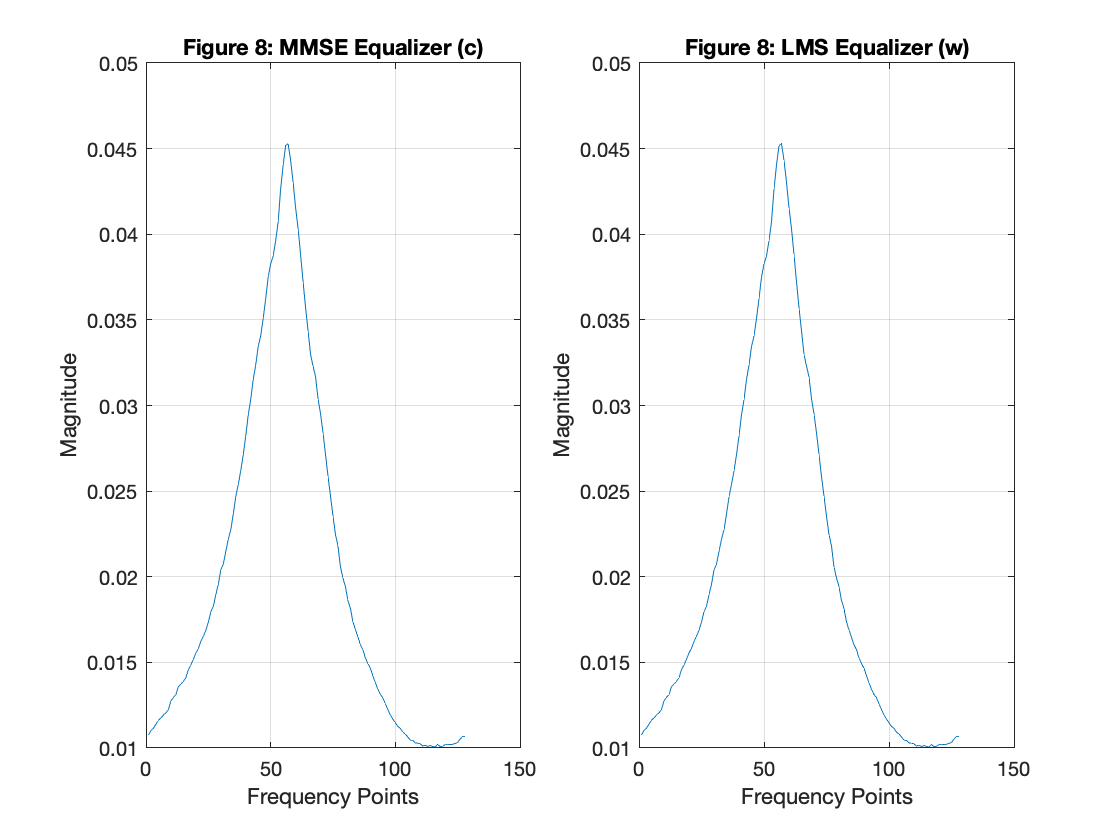


% Plot comparison using subplot, since overlapping would result in a
% non-discernable graph
figure(); 
subplot(1, 2, 1); plot(abs(fft(c))); title("Figure 8: MMSE Equalizer (c)");
xlabel("Frequency Points"); ylabel("Magnitude"); grid on;
subplot(1, 2, 2); plot(abs(fft(w))); title("Figure 8: LMS Equalizer (w)");
xlabel("Frequency Points"); ylabel("Magnitude"); grid on;



% LMS Adaptive with Interference Equalizer 
w2 = zeros(128, 1); w2(re_delay) = 1; data2 = zeros(128, 1); u2 = zeros(128, 1); 
j = sqrt(-1); squared_error2 = 0; lim = 5000000; 

for iter=1:lim
    % Randomly compute sampled data
    val = randsample([-1, 1], 1) * (1/sqrt(2)) + randsample([-1, 1], 1) * (j/sqrt(2));

    % Cyclically shift channel output into output array, and add val in front
    data2 = circshift(data2, 1); data2(1) = val;
    % channel output 
    val = 0;
    for i=1:128
        val = val + impulse_response(i) * data2(i); 
    end
    val = val + sqrt(10) * exp(-sqrt(-1) * pi * iter / 3);
    
    % Cyclically shift channel output into output array, and add val in front
    u2 = circshift(u2, 1); u2(1) = val;
    
    % Calculate the error  
    y = 0;
    for i=1:128
        y = y + u2(i) * w2(i);
    end
    e = data2(re_delay) - y; 
    % Adjust the step size and update the w in gradient descent
    if iter >= 0.95 * lim
        squared_error2 = squared_error2 + abs(e)^2;
    end
    w2 = w2 + del * e * conj(u2);
end

SINR2 = 0.05 * lim / squared_error2

SINR2 = 1.0591e+03

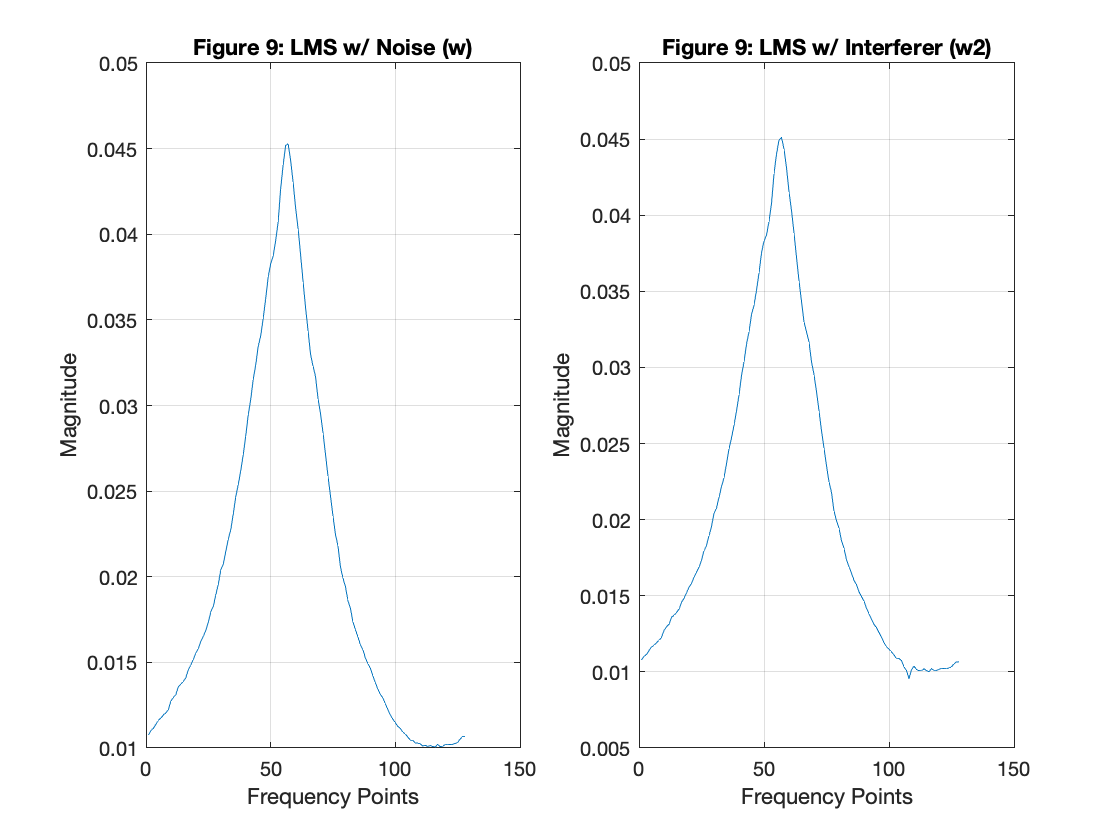


% Plot comparison between noise and interference
figure(); 
subplot(1, 2, 1); plot(abs(fft(w))); title("Figure 9: LMS w/ Noise (w)");
xlabel("Frequency Points"); ylabel("Magnitude"); grid on;
subplot(1, 2, 2); plot(abs(fft(w2))); title("Figure 9: LMS w/ Interferer (w2)");
xlabel("Frequency Points"); ylabel("Magnitude"); grid on;